% 鸢尾花聚类
% 此示例说明自组织映射神经网络如何以拓扑方式将鸢尾花聚类为各个类，
% 提供对花类型的深入了解以及用于进一步分析的实用工具。
% 
% 问题：对鸢尾花进行聚类
% 在此示例中，我们尝试构建一个将鸢尾花聚类成多个自然类的神经网络，
% 以使相似的类分组在一起。每朵鸢尾花都用四个特征进行描述：

% 萼片长度 (cm)% 
% 萼片宽度 (cm)% 
% 花瓣长度 (cm)% 
% 花瓣宽度 (cm)% 
% 这是一个聚类问题的示例，我们希望根据样本之间的相似性将样本分组到各个类。我们要创建一个神经网络，该网络不仅可以为已知输入创建类定义，还能相应地对未知输入进行分类。
% 
% 为什么使用自组织映射神经网络？
% 自组织映射 (SOM) 非常擅长创建分类。而且，分类保留了关于哪些类与其他类最相似的拓扑信息。自组织映射可以创建为任何所需的详细程度级别。它们特别适合对存在于多个维度且具有复杂形状的相连特征空间的数据进行聚类。它们非常适合对鸢尾花进行聚类。
% 四个花属性将作为 SOM 的输入，SOM 将它们映射到二维神经元层。
% 

## 准备数据

通过将数据组织成输入矩阵 X，为 SOM 设置聚类问题数据。 输入矩阵的每个第 i 列将具有四个元素，表示在一朵花上获取的四个测量值。 使用以下命令加载一个这样的数据集。

x = iris_dataset;
% 我们可以查看输入 X 的大小。
% 请注意，X 有 150 列。这些列代表 150 组鸢尾花属性。它具有四行，表示四个测量值。

size(x) % ans =     4   150

ans =      4   150


## 使用神经网络进行聚类

下一步是创建一个用于学习聚类的神经网络。 使用 selforgmap 创建自组织映射，通过选择每个层维度中的神经元数量来对样本进行所需详细程度的分类。 对于此示例，我们将尝试具有以 8×8 六边形网格排列的 64 个神经元的二维层。通常，使用更多神经元可以获得更多细节，而使用更多维度则可对更复杂特征空间的拓扑进行建模。 输入大小为 0，因为网络尚未配置成与我们的输入数据相匹配。这将在训练网络时进行。

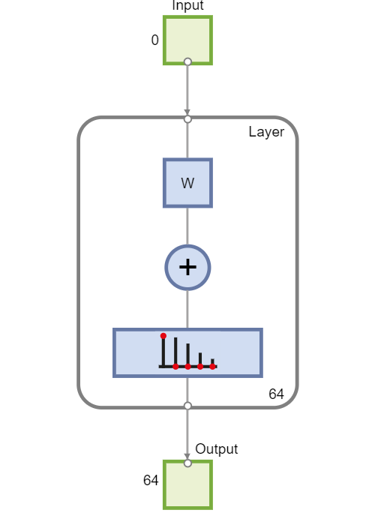

net = selforgmap([8 8]);
view(net)

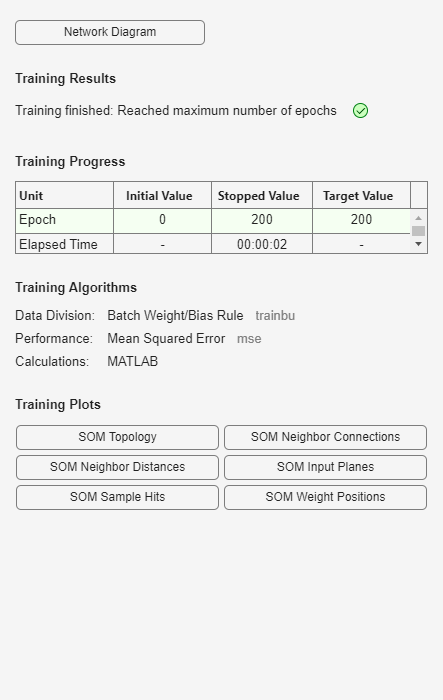



% 现在网络已准备好使用 train 进行优化。
% 神经网络训练工具显示正在接受训练的网络和用于训练该网络的算法。它还显示训练过程中的训练状态以及停止训练的条件（以绿色突出显示）。
% 底部的按钮用于打开有用的绘图，这些图可以在训练期间和训练后打开。算法名称和绘图按钮旁边的链接可打开有关这些主题的文档。

[net,tr] = train(net,x);

nntraintool

Unrecognized function or variable 'nntraintool'.



nntraintool('close')
% 这里使用自组织映射计算每个训练输入的类向量。这些分类涵盖了已知花朵所填充的特征空间，
% 它们现在可用于对新花朵进行相应分类。网络输出将是一个 64×150 矩阵，
% 其中每个第 i 列表示第 i 个输入向量（其第 j 个元素为 1）的第 j 个聚类。

% 函数 vec2ind 针对每个向量返回输出为 1 的神经元的索引。
% 对于由 64 个神经元表示的 64 个聚类，索引值范围在 1 到 64 之间。

y = net(x);
cluster_index = vec2ind(y);
% 使用 plotsomtop 绘制位于 8×8 六边形网格中的 64 个神经元的自组织映射拓扑。
% 每个神经元都已经过学习，可代表不同的花类，相邻的神经元通常代表相似的类。

plotsomtop(net)
% 使用 plotsomhits 计算每朵花的类，并显示每个类中的花朵数量。
% 具有大量命中的神经元区域所表示的类代表相似的填充度高的特征空间区域。
% 而命中较少的区域表示填充稀疏的特征空间区域。
plotsomhits(net,x)


% 使用 plotsomnc 显示神经元邻点连接。邻点通常用于对相似样本进行分类。
plotsomnc(net)

% plotsomnd 显示每个神经元的类与其邻点的距离（以欧几里德距离表示）。
% 浅色连接表示输入空间的高度连接区域。
% 而深色连接表示的类代表相距很远且相互之间很少或没有花朵的特征空间区域。

% 将较大输入空间区域分开的深色连接的长边界表明，边界两侧的类代表特征非常不同的花朵。

plotsomnd(net)
% 使用 plotsomplanes 显示四个输入特征中每个特征的权重平面。
% 它们是权重的可视化，这些权重将每个输入连接到以 8×8 六边形网格排列的 64 个神经元中的每一个。
% 深色代表较大权重。如果两个输入具有相似的权重平面（它们的颜色梯度可能相同或相反），则表明它们高度相关。

plotsomplanes(net)

% 此示例说明了如何设计一个根据鸢尾花的四个特征对鸢尾花进行聚类的神经网络。
% 请浏览其他示例和文档，以便更深入地了解神经网络及其应用。